# **Отчёт по лабораторной работе 1.**

# **Выполнил Барыбин С.М.**

**Задание 1**

Разработал функции в матлаб, реализующие необходимые методы.

**Задание 2**

Не помня номер компьютера в компьютерном классе, выполнил работу в соответствии с номером по списку. Таким образом тестовая функция:


$$f\left(x\right)=x^4 +x^2 +x+1,x\text{ }\epsilon \text{ }\left\lbrace -1;0\right\rbrace$$


**Задание 3**

Требуется построить график и для всех методов изучить скорость работы. Сравнить методы друг с другом. Объяснить результаты.

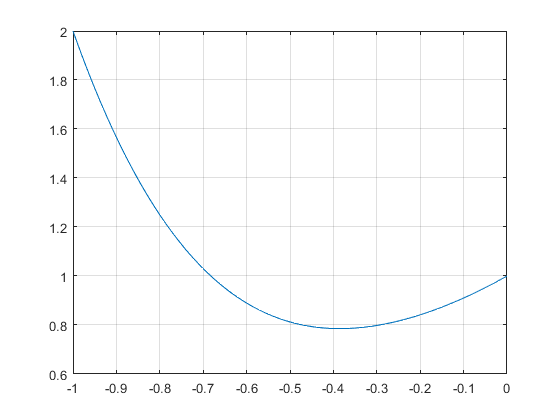

clear
x = -1:.01:0;
y = x.^4 + x.^2 + x + 1;
plot(x,y);
grid on

f = @(x)x^4 + x^2 + x + 1; 

 График построен.

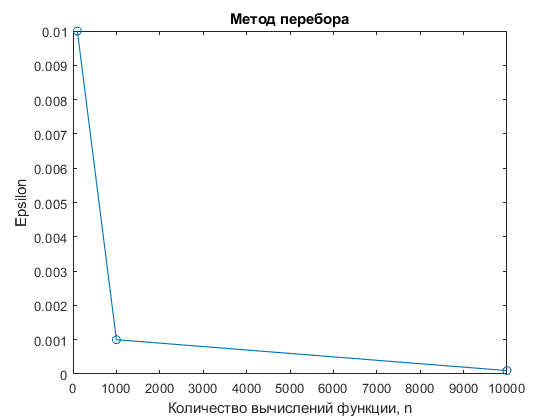

format long

eps = [0.01 0.001 0.0001 0.0001]; % изменил последнюю точность
a = -1;
b = 0;
for i = 1:length(eps)
    [fmin(i), xmin(i), n(i)] = perebor(f, a, b, eps(i));
end
% Строим график eps против n
plot(n, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод перебора');

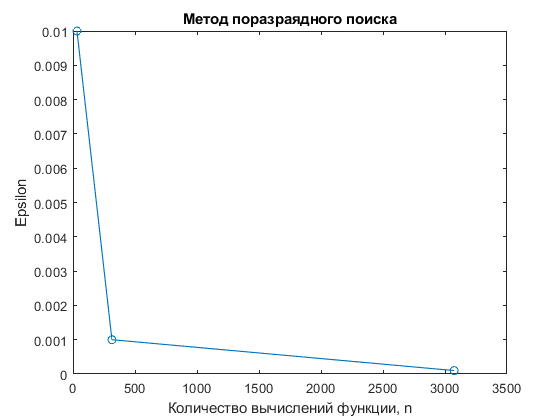

format long

eps = [0.01 0.001 0.0001]; % изменил последнюю точность
a = -1;
b = 0;
n = 1:length(eps);
for i = 1:length(eps)
    [fmin(i), xmin(i), n(i)] = porazr(f, a, b, eps(i));
end
% Строим график eps против n
plot(n, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод поразраядного поиска');

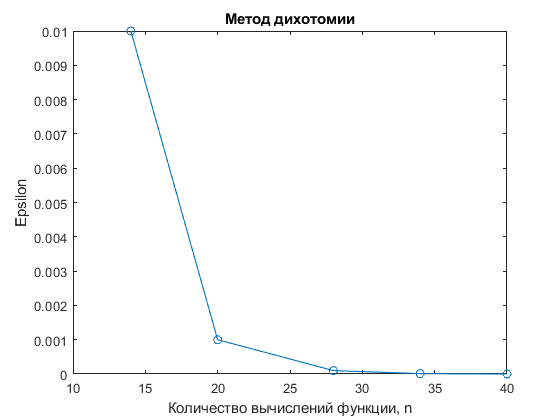


format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n1 = 1:length(eps);
for i = 1:length(eps)
    [fmin1(i), xmin1(i), n1(i)] = dihotomy(f, a, b, eps(i));
end
% Строим график eps против n
plot(n1, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод дихотомии');

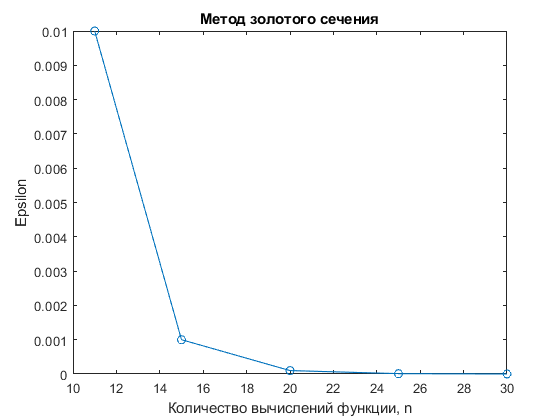

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n2 = 1:length(eps);
for i = 1:length(eps)
    [fmin(i), xmin(i), n2(i)] = gold(f, a, b, eps(i));
end
% Строим график eps против n
plot(n2, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод золотого сечения');

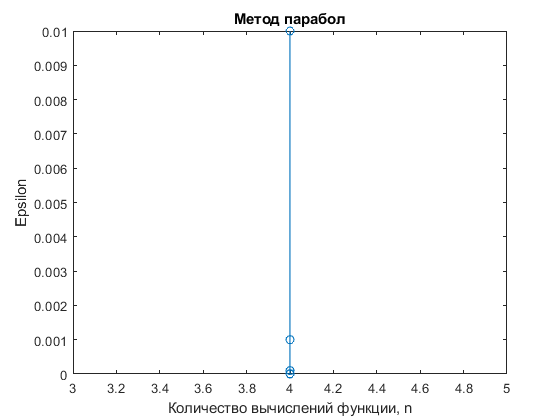

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n3 = 1:length(eps);
for i = 1:length(eps)
    [fmin(i), xmin(i), n3(i)] = parabols(f, a, b, eps(i));
end
% Строим график eps против n
plot(n3, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод парабол');

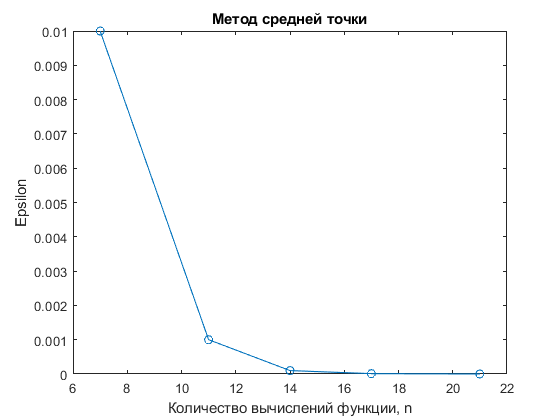

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n4 = 1:length(eps);
for i = 1:length(eps)
    [fmin(i), xmin(i), n4(i)] = ave_point(f, a, b, eps(i));
end
% Строим график eps против n
plot(n4, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод средней точки');

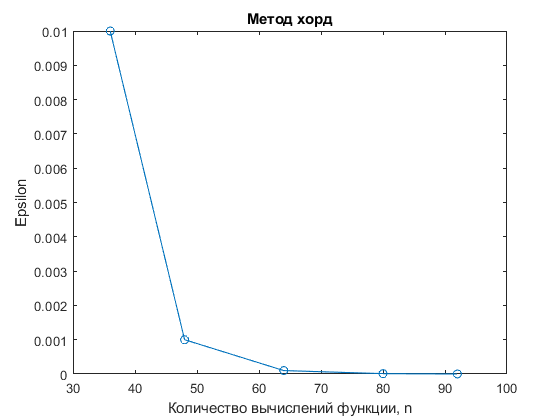

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n5 = 1:length(eps);
for i = 1:length(eps)
    [fmin(i), xmin(i), n5(i)] = hords(f, a, b, eps(i));
end
% Строим график eps против n
plot(n5, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод хорд');

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n6 = 1:length(eps);
for i = 1:length(eps)
    [fmin(i), xmin(i), n6(i)] = newton(f, a, b,-0.35, eps(i));
end
% Строим график eps против n
plot(n6, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
set(gca, 'YScale', 'log'); % Логарифмическая шкала по оси Y для наглядности
title('Метод Ньютона');

Все методы реализованы, проведена минимизация функции. Для наглядности построим график зависимости eps(n) для всех методов, кроме поразрядного поиска и перебора

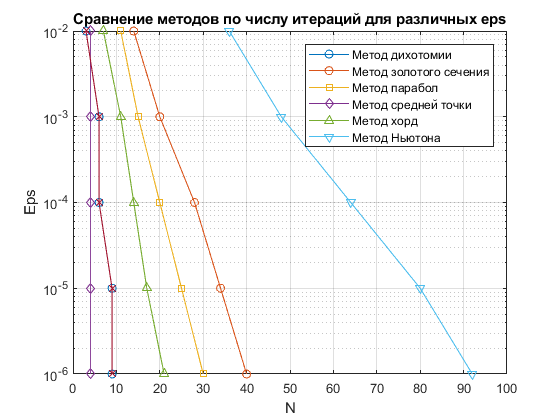

hold on
ylim = [10^-2 10^-6];
plot(n1, eps, '-o'); % Линия с маркерами для метода дихотомии
plot(n2, eps, '-s'); % Линия с квадратными маркерами для метода золотого сечения
plot(n3, eps, '-d'); % Линия с ромбовидными маркерами для метода парабол
plot(n4, eps, '-^'); % Линия с треугольными маркерами для метода средней точки
plot(n5, eps, '-v'); % Линия с перевернутыми треугольниками для метода хорд
plot(n6, eps, '-x'); % Линия с крестиками для метода Ньютона

grid on
ylabel('Eps');
xlabel('N');
legend({'Метод дихотомии', 'Метод золотого сечения', 'Метод парабол', 'Метод средней точки', 'Метод хорд', 'Метод Ньютона'});
title('Сравнение методов по числу итераций для различных eps');